%--------------------------
clear all;
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

MatNames = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames1 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames3 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
HDRlNames2 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};


%-----------------------------------
% Exp3 load
%-----------------------------------
%---------------------------------------
% (HDR,Materials,Shape,Participants)
%---------------------------------------
Exp3RowHMSP = zeros(30, 4, 6, 5);

%indivsual folder
dirInfo1 = dir(resultpath);
FolderNames1 = {dirInfo1(~ismember({dirInfo1(:).name}, {'.', '..'})).name};
numFolders1 = sum(~ismember({dirInfo1(:).name}, {'.', '..'}));

%indivisual name
subject_name = {};

for foldernum1 = 1:numFolders1
    namefolder = fullfile(resultpath, FolderNames1{foldernum1});

    %exp data
    dirInfo2 = dir(namefolder);
    FileNames2 = {dirInfo2(~ismember({dirInfo2(:).name}, {'.', '..'})).name};
    numFile2 = sum(~ismember({dirInfo2(:).name}, {'.', '..'}));
    for foldernum2 = 1:numFile2
        datafile = fullfile(namefolder,FileNames2{foldernum2});
        disp(datafile);

        csvData = readtable(datafile,'ReadVariableNames', true,'VariableNamingRule','preserve');
        headers = readtable(datafile,'VariableNamingRule','preserve').Properties.VariableNames;
        avscore = reshape(mean(csvData{:,:},1),1,[]);

        %words
        words = split(FileNames2{foldernum2},{'_', '.'});
        if ~any(strcmp(subject_name,words{1}))
            subject_name{end + 1} = words{1};
        end

        for i = 1:length(headers)
            nameStr = headers{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            HDRIndex = find(HDRNames == idNum);
            MatIndex = find(strcmp(MatNames,words{2}));
            ShapeIndex = find(strcmp(ShapeNames,words{3}));
            SubjectsIndex = find(strcmp(FolderNames1,words{1}));
            if ~isempty(HDRIndex) && ~isempty(MatIndex) && ~isempty(ShapeIndex) && ~isempty(SubjectsIndex)
                Exp3RowHMSP(HDRIndex, MatIndex, ShapeIndex,SubjectsIndex) = Exp3RowHMSP(HDRIndex, MatIndex,ShapeIndex, SubjectsIndex) + avscore(i);
            end
        end
    end
end

.\results\Jiang\Jiang_cu0025_boardA.csv
.\results\Jiang\Jiang_cu0025_boardB.csv
.\results\Jiang\Jiang_cu0025_boardC.csv
.\results\Jiang\Jiang_cu0025_bunny.csv
.\results\Jiang\Jiang_cu0025_dragon.csv
.\results\Jiang\Jiang_cu0025_sphere.csv
.\results\Jiang\Jiang_cu0129_boardA.csv
.\results\Jiang\Jiang_cu0129_boardB.csv
.\results\Jiang\Jiang_cu0129_boardC.csv
.\results\Jiang\Jiang_cu0129_bunny.csv
.\results\Jiang\Jiang_cu0129_dragon.csv
.\results\Jiang\Jiang_cu0129_sphere.csv
.\results\Jiang\Jiang_pla0075_boardA.csv
.\results\Jiang\Jiang_pla0075_boardB.csv
.\results\Jiang\Jiang_pla0075_boardC.csv
.\results\Jiang\Jiang_pla0075_bunny.csv
.\results\Jiang\Jiang_pla0075_dragon.csv
.\results\Jiang\Jiang_pla0075_sphere.csv
.\results\Jiang\Jiang_pla0225_boardA.csv
.\results\Jiang\Jiang_pla0225_boardB.csv
.\results\Jiang\Jiang_pla0225_boardC.csv
.\results\Jiang\Jiang_pla0225_bunny.csv
.\results\Jiang\Jiang_pla0225_dragon.csv
.\results\Jiang\Jiang_pla0225_sphere.csv
.\results\Nakajima\Nakajima_cu00

disp(subject_name);

    {'Jiang'}    {'Nakajima'}    {'ODA'}    {'Satou'}    {'wang'}



%zscore化
Exp3ZsHMSP = zeros(size(Exp3RowHMSP));
for subject = 1:size(Exp3RowHMSP,4)
    for model = 1:size(Exp3RowHMSP,3)
        for material = 1:size(Exp3RowHMSP,2)
            Exp3ZsHMSP(:, material,model,subject) = zscore(Exp3RowHMSP(:,material,model,subject));
        end
    end
end

%---------------------------------------
% (HDR,Material,Shape)
%---------------------------------------
Exp3ZsHMS = mean(Exp3ZsHMSP,4);

% 標準誤差
error_Exp3HMS = std(Exp3ZsHMSP, 0, 4) / sqrt(size(Exp3ZsHMSP, 4));
%正規化
Exp3HMSNorm = zeros(size(Exp3ZsHMS));
error_Exp3HMSNorm = zeros(size(error_Exp3HMS));
for i = 1:size(Exp3ZsHMS, 3)
    for j = 1:size(Exp3ZsHMS,2)
        hdr_min = min(Exp3ZsHMS(:, j, i));
        hdr_max = max(Exp3ZsHMS(:, j, i));
        
        Exp3HMSNorm(:, j, i) = 2 * (Exp3ZsHMS(:, j, i) - hdr_min) / (hdr_max - hdr_min)-1;
        error_Exp3HMSNorm(:, j, i) = error_Exp3HMS(:, j, i) / (hdr_max - hdr_min);
    end
end

%---------------------------------------
% (HDR,Material)
%---------------------------------------
Exp3ZsHM = mean(Exp3ZsHMS,3);
%{
z-score化
Exp3MHZs = zeros(size(Exp3RowMH));
for i = 1:size(Exp3RowMH, 1)
    Exp3MHZs(i, :) = zscore(Exp3RowMH(i, :));
end
%}
% 標準誤差
Exp3HM_reshaped = reshape(Exp3RowHMSP,size(Exp3RowHMSP,1),size(Exp3RowHMSP,2),[]);
error_Exp3HM = std(Exp3HM_reshaped, 0, 3)/ sqrt(size(Exp3RowHMSP,3)+size(Exp3RowHMSP,4));
%正規化
Exp3HMNorm = zeros(size(Exp3ZsHM));
error_Exp3HMNorm = zeros(size(error_Exp3HM));
for i = 1:size(Exp3ZsHM, 2)
    hdr_min = min(Exp3ZsHM(:, i));
    hdr_max = max(Exp3ZsHM(:, i));
    
    Exp3HMNorm(:,i) = 2 * (Exp3ZsHM(:, i) - hdr_min) / (hdr_max - hdr_min)-1;
    error_Exp3HMNorm(:, i) = error_Exp3HM(:, i) / (hdr_max - hdr_min);
end
%---------------------------------------
% (HDR,Shape)
%---------------------------------------
Exp3ZsHS = mean(Exp3ZsHMS,2);
%{
z-score化
Exp3SHZs = zeros(size(Exp3RowSH));
for i = 1:size(Exp3RowSH, 1)
    Exp3SHZs(i, :) = zscore(Exp3RowSH(i, :));
end
%}
% 標準誤差
Exp3HS_reshaped = reshape(Exp3RowHMSP,size(Exp3RowHMSP,1),size(Exp3RowHMSP,2),[]);
error_Exp3HS = std(Exp3HS_reshaped, 0, 3)/ sqrt(size(Exp3RowHMSP,3)+size(Exp3RowHMSP,4));
%正規化
Exp3HSNorm = zeros(size(Exp3ZsHS));
error_Exp3HSNorm = zeros(size(error_Exp3HS));
for i = 1:size(Exp3ZsHS, 2)
        hdr_min = min(Exp3ZsHS(:,i));
        hdr_max = max(Exp3ZsHS(:,i));
        
        Exp3HSNorm(:,i) = 2 * (Exp3ZsHS(:,i) - hdr_min) / (hdr_max - hdr_min)-1;
        error_Exp3HSNorm(:,i) = error_Exp3HS(:,i) /(hdr_max - hdr_min);
end
%---------------------------------------
% (HDR)
%---------------------------------------
Exp3ZsH = mean(Exp3ZsHM,2);

% 標準誤差
Exp3H_reshaped = reshape(Exp3RowHMSP,size(Exp3RowHMSP,1),[]);
error_Exp3H = std(Exp3H_reshaped, 0, 3)/ sqrt(size(Exp3RowHMSP,3)+size(Exp3RowHMSP,4));
%正規化
Exp3HNorm = zeros(size(Exp3ZsH));
error_Exp3HNorm = zeros(size(error_Exp3H));
hdr_min = min(Exp3ZsH(:));
hdr_max = max(Exp3ZsH(:));

Exp3HNorm(:) = 2 * (Exp3ZsH(:) - hdr_min) / (hdr_max - hdr_min)-1;
error_Exp3HNorm(:) = error_Exp3H(:) /(hdr_max - hdr_min);


% data save
save(strcat(Datapath,'Exp3_data.mat'),'Exp3HMSNorm','error_Exp3HMSNorm','Exp3HMNorm','error_Exp3HMNorm','Exp3HSNorm','error_Exp3HSNorm','Exp3HNorm','error_Exp3HNorm');

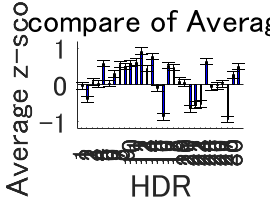

%-----------------------------------
% Exp3 All Average
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb = bar(x + bar_width/2, AvExp3zscore, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, AvExp3zscore, error_av_O, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Average z-score', 'FontSize', 16);
title('compare of Average', 'FontSize', 16);
plotname = strcat(ana_result, '/Exp3_Average.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue Load
%-----------------------------------
load('./inouedata/reshaped/z_psvList.mat')

load('./inouedata/reshaped/z_conditionList_2.mat')
condition_exp2 = experiment_condition;

%-----------------------------------
% (HDR,Material)
%-----------------------------------
searchColumn = [1,3];

groupColumns = condition_exp2(:, searchColumn);

columnCells = num2cell(groupColumns, 1);
[MatgroupIdx, uniqueGroups1,uniqueGroups2] = findgroups(columnCells{:});

groupMeans = splitapply(@(x) mean(x, 1), psv_experiment2, MatgroupIdx);

%正規化
InoueMHNorm = zeros(size(groupMeans));
for i = 1:size(groupMeans,1)
    hdr_min = min(groupMeans(i, :));
    hdr_max = max(groupMeans(i, :));
    
    InoueMHNorm(i, :) = 2 * (groupMeans(i, :) - hdr_min) / (hdr_max - hdr_min)-1;
end
InoueHMNorm = permute(InoueMHNorm,[2,1]);

InoueMatname = strcat(uniqueGroups1,'-', uniqueGroups2);
%-----------------------------------
% (HDR,Shape)
%-----------------------------------
searchColumn = 2;

groupColumns = condition_exp2(:, searchColumn);

columnCells = num2cell(groupColumns, 1);
[ShapegroupIdx, uniqueGroups1] = findgroups(columnCells{:});

groupMeans = splitapply(@(x) mean(x, 1), psv_experiment2, ShapegroupIdx);

%正規化
InoueSHNorm = zeros(size(groupMeans));
for i = 1:size(groupMeans,1)
    hdr_min = min(groupMeans(i, :));
    hdr_max = max(groupMeans(i, :));
    
    InoueSHNorm(i, :) = 2 * (groupMeans(i, :) - hdr_min) / (hdr_max - hdr_min)-1;
end
InoueHSNorm = permute(InoueSHNorm,[2,1]);

InoueShapeName = uniqueGroups1;
%-----------------------------------
% (HDR,Material,Shape)
%-----------------------------------
InoueRowHMS = zeros(30,4,6);

for i = 1:size(psv_experiment2,1)
    MatIdx = MatgroupIdx(i);
    ShapeIdx = ShapegroupIdx(i);
    InoueRowHMS(:,MatIdx,ShapeIdx) = psv_experiment2(i,:);
end
%正規化
InoueHMSNorm = zeros(size(InoueRowHMS));
for mat = 1:size(InoueRowHMS,2)
    for shape = 1:size(InoueRowHMS,3)
        hdr_min = min(InoueRowHMS(:,mat, shape));
        hdr_max = max(InoueRowHMS(:,mat, shape));
        
        InoueHMSNorm(:,mat, shape) = 2 * (InoueRowHMS(:,mat,shape) - hdr_min) / (hdr_max - hdr_min)-1;
    end
end

%-----------------------------------
% (HDR)
%-----------------------------------
InoueRowH = mean(groupMeans, 1);
InoueHNorm_b = zeros(size(InoueRowH));
for i = 1:size(InoueRowH,1)
    hdr_min = min(InoueRowH(i, :));
    hdr_max = max(InoueRowH(i, :));
    
    InoueHNorm_b(i, :) = 2 * (InoueRowH(i, :) - hdr_min) / (hdr_max - hdr_min)-1;
end
InoueHNorm = permute(InoueHNorm_b,[2,1]);

% data save
save(strcat(Datapath,'Inoue_data.mat'),'InoueHMSNorm','InoueHMNorm','InoueHSNorm','InoueHNorm');

%-----------------------------------
% Inoue material
%-----------------------------------
for row = 1:size(InoueMHNorm,1)
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueMHNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueMHNorm(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueMatname{row}], 'FontSize', 16);

    plotname = strcat(ana_result, '/I_M_', InoueMatname{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Inoue Shape
%-----------------------------------
for row = 1:size(InoueSHNorm,1)
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueSHNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueSHNorm(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueShapeName{row}], 'FontSize', 16);

    plotname = strcat(ana_result, '/I_S_', InoueShapeName{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Inoue material shape
%-----------------------------------
for matnum = 1:size(InoueHMSNorm,1)
    for shapenum = 1:size(InoueHMSNorm,3)
        figure;
        hold on;
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, InoueHMSNorm(matnum, :, shapenum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        %errorbar(x + bar_width/2, InoueMHSNorm(matnum, :, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' InoueMatname{matnum} '&' InoueShapeName{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    
        plotname = strcat(ana_result, '/I_MS_', InoueMatname{matnum},InoueShapeName{row},'.jpg');
        saveas(gcf, plotname);
        hold off;
    end
end


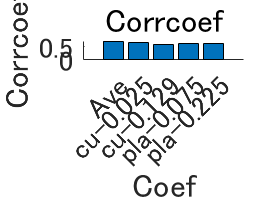

%-----------------------------------
% Exp3 vs Inoue Coef
%-----------------------------------
corrColumn = {'Ave','cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
corrVector = zeros(size(AvExp3zscore, 1)+1, 1);

correlation = corrcoef(AvExp3zscore, InoueHNorm_b);
corrVector(1) = correlation(1, 2);
for i = 1:4
    correlation = corrcoef(Exp3HMSNorm(i, :), InoueMHNorm(i, :));
    corrVector(i+1) = correlation(1, 2);
end

figure;
hold on;
bar(corrVector);
set(gca, 'XTick', 1:length(corrColumn));
set(gca, 'XTickLabel', corrColumn, 'FontSize', 14);
xlabel('Coef', 'FontSize', 16); 
ylabel('Corrcoef', 'FontSize', 16);
title('Corrcoef', 'FontSize', 16);
plotname = strcat(ana_result, '/A_Coef_1.jpg');
saveas(gcf, plotname);
hold off;

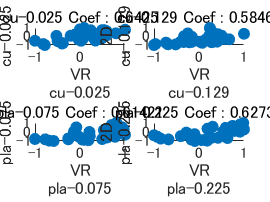


figure;
hold on;
for i = 1:4
    subplot(2, 2, i);
    scatter(Exp3HMSNorm(i, :), InoueMHNorm(i, :), 'filled');
    xlabel(['VR', MatNames2(i)]);
    ylabel(['2D', MatNames2(i)]);
    title(string(MatNames2(i)) + ' Coef : ' + string(corrVector(i+1)));
end
plotname = strcat(ana_result, '/A_Coef_2.jpg');
saveas(gcf, plotname);
hold off;

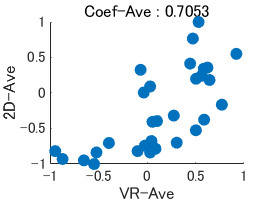


figure;
hold on;
scatter(AvExp3zscore, InoueHNorm_b, 'filled');
xlabel('VR-Ave');
ylabel('2D-Ave');
title('Coef-Ave : ' + string(corrVector(1)));
plotname = strcat(ana_result, '/A_Coef_3.jpg');
saveas(gcf, plotname);
hold off;

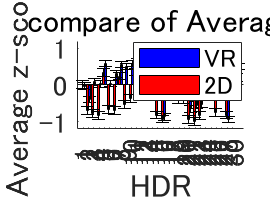

%-----------------------------------
% Exp3 vs Inoue graph
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb1 = bar(x + bar_width/2, AvExp3zscore, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh1 = errorbar(x + bar_width/2, AvExp3zscore, error_av_O, 'k', 'linestyle', 'none');
avb2 = bar(x - bar_width/2, InoueHNorm_b, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
avh2 = errorbar(x - bar_width/2, InoueHNorm_b, error_av_I, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Average z-score', 'FontSize', 16);
title('compare of Average', 'FontSize', 16);
legend([avb1, avb2], {'VR', '2D'}, 'Location', 'best');
plotname = strcat(ana_result, '/O_Average_hikaku.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp2 load
%-----------------------------------
resultmitsuba = "resultmitsuba/";
exp2path = "../Exp2/";

Exp2RowHMP = zeros(15, 4, 6);
exp2_subjects = {};

%allfileload
dirInfo = dir(exp2path + resultmitsuba);
exp2filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

%name
for foldernum =1:numFiles
    words = split(exp2filesNames{foldernum},{'_', '.'});
    if ~any(strcmp(exp2_subjects,words{1}))
        exp2_subjects{end + 1} = words{1};
    end
end

for foldernum =1:numFiles
    filename = fullfile(exp2path + resultmitsuba, exp2filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(MatNames1)
        sheetName = MatNames1{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};

        words = split(exp2filesNames{foldernum},{'_', '.'});

        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            HDRIndex = find(HDRlNames2 == idNum);
            MatIndex = find(strcmp(MatNames1, sheetName));
            ParticipantsIndex = find(strcmp(exp2_subjects,words{1}));
            if ~isempty(HDRIndex) && ~isempty(MatIndex) && ~isempty(ParticipantsIndex)
                Exp2RowHMP(HDRIndex,MatIndex,ParticipantsIndex) = Exp2RowHMP(HDRIndex,MatIndex,ParticipantsIndex) + scores(i)/5;
            end
        end
    end
end

..\Exp2\resultmitsuba\kawahara_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\killian_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\kyou_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\miyoshi_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\okamoto_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\satou_mitsuba_exp2.xlsx


%z-score
Exp2HMPZs = zeros(size(Exp2RowHMP));
for subjects = 1:size(Exp2RowHMP, 3)
    for mat = 1:size(Exp2RowHMP,2)
        Exp2HMPZs(:,mat,subjects) = zscore(Exp2RowHMP(:,mat,subjects));
    end
end
%-----------------------------------
% (HDR,Material)
%-----------------------------------
Exp2RowHM = mean(Exp2RowHMP,3);
%標準誤差
error_Exp2MH = std(Exp2RowHMP, 0, 3)/ sqrt(size(Exp2RowHMP,3));
%正規化
Exp2MHNorm = zeros(size(Exp2RowHM));
error_Exp2MH_Norm = zeros(size(error_Exp2MH));
for i = 1:size(Exp2RowHM, 2)
    hdr_min = min(Exp2RowHM(:,i));
    hdr_max = max(Exp2RowHM(:,i));

    Exp2MHNorm(:,i) = 2 * (Exp2RowHM(:,i) - hdr_min) / (hdr_max - hdr_min)-1;
    error_Exp2MH_Norm(:,i) = error_Exp2MH(:,i) / (hdr_max - hdr_min);
end

Exp2MHNorm30 = zeros(4, 30);
[isMember, colIdx] = ismember(HDRlNames2, HDRNames);
Exp2MHNorm30(:, colIdx(isMember)) = Exp2HMPZs;
error_Exp2MH30(:,colIdx(isMember)) = error_Exp2MH_Norm;

%-----------------------------------
% exp2 VS VR
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(HDRNames);

    % exp2のプロット
    b2 = bar(x - bar_width/2, Exp2MHNorm30(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', '2D'); 
    h2 = errorbar(x - bar_width/2, Exp2MHNorm30(row, :), error_Exp2MH(row,:), 'k', 'linestyle', 'none');

    % exp3のプロット
    b3 = bar(x + bar_width/2, Exp3HMSNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    h3 = errorbar(x + bar_width/2, Exp3HMSNorm(row, :), error_Exp3HMS(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames));
    set(gca, 'XTickLabel', HDRNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    legend([b2,b3],{'2D','3D'}, 'Location', 'best');

    plotname = strcat(ana_result, '/', MatNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_exp2 = Exp2MHNorm30(row, :);
    data_exp3 = Exp3HMSNorm(row, :);
    corr_matrix = corrcoef(data_exp2, data_exp3);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);
%}

%-----------------------------------
% Exp1 load
%-----------------------------------
resultmitsuba = "resultmitsuba/";
exp1path = "../test/";

Exp1RowMHP = zeros(4, 15, 6);
exp1_subjects = {};

%allfileload
dirInfo = dir(exp1path + resultmitsuba);
exp1filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

%name
for foldernum =1:numFiles
    words = split(exp1filesNames{foldernum},{'_', '.'});
    if ~any(strcmp(exp1_subjects,words{1}))
        exp1_subjects{end + 1} = words{1};
    end
end

for foldernum =1:numFiles
    filename = fullfile(exp1path + resultmitsuba, exp1filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(MatNames1)
        sheetName = MatNames1{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};

        words = split(exp1filesNames{foldernum},{'_', '.'});

        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            HDRIndex = find(HDRlNames2 == idNum);
            MatIndex = find(strcmp(MatNames1, sheetName));
            ParticipantsIndex = find(strcmp(exp1_subjects,words{1}));
            if ~isempty(HDRIndex) && ~isempty(MatIndex) && ~isempty(ParticipantsIndex)
                Exp1RowMHP(MatIndex, HDRIndex,ParticipantsIndex) = Exp1RowMHP(MatIndex, HDRIndex,ParticipantsIndex) + scores(i)/5;
            end
        end
    end
end

..\test\resultmitsuba\kawahara_mitsuba.xlsx
..\test\resultmitsuba\killian_mitsuba.xlsx
..\test\resultmitsuba\kyou_mitsuba.xlsx
..\test\resultmitsuba\miyoshi_mitsuba.xlsx
..\test\resultmitsuba\okamoto_mitsuba.xlsx
..\test\resultmitsuba\satou_mitsuba.xlsx


%-----------------------------------
% (Material,HDR)
%-----------------------------------
Exp1RowMH = mean(Exp1RowMHP,3);
%標準誤差
error_Exp1MH = std(Exp1RowMHP, 0, 3)/ sqrt(size(Exp1RowMHP,3));
%正規化
Exp1MHNorm = zeros(size(Exp1RowMH));
error_Exp1MH_Norm = zeros(size(error_Exp1MH));
for i = 1:size(Exp1RowMH, 1)
    hdr_min = min(Exp1RowMH(i, :));
    hdr_max = max(Exp1RowMH(i, :));

    Exp1MHNorm(i, :) = 2 * (Exp1RowMH(i, :) - hdr_min) / (hdr_max - hdr_min)-1;
    error_Exp1MH_Norm(i,:) = error_Exp1MH(i,:) / (hdr_max - hdr_min);
end

Exp1MHNorm30 = zeros(4, 30);
[isMember, colIdx] = ismember(HDRlNames2, HDRNames);
Exp1MHNorm30(:, colIdx(isMember)) = Exp1MHNorm;
error_Exp1MH30(:,colIdx(isMember)) = error_Exp1MH_Norm;